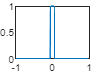

% fft_example - Chapter 3 fft example 
w=0.055; %rectangle half-width (m) 
L=2; %vector side length (m) 
M=200; %number of samples 
dx=L/M; %sample interval (m) 

x=-L/2:dx:L/2-dx; %coordinate vector 
f=rect(x/(2*w)); %signal vector

figure(1) 
plot(x,f); %plot f vs x

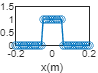


figure(2) 
plot(x,f,'-o'); %plot f vs x 
axis([-0.2 0.2 0 1.5]); 
xlabel('x(m)'); 

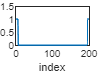


f0=fftshift(f); %shift f 
figure(4) 
plot(f0); 
axis([0 200 0 1.5]); 
xlabel('index');

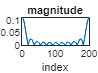


F0=fft(f0)*dx; %FFT and scale 
figure(5) 
plot(abs(F0)); %plot magnitude 
title('magnitude'); 
xlabel('index'); 

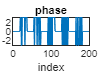


figure(6) 
plot(angle(F0)); %plot phase 
title('phase'); 
xlabel('index'); 

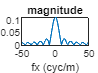


F=fftshift(F0); %center F
fx=-1/(2*dx):1/L:1/(2*dx)-(1/L); %freq cords 
 
figure(7) 
plot(fx,abs(F)); %plot magnitude 
title('magnitude'); 
xlabel('fx (cyc/m)'); 

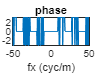

 
figure(8) 
plot(fx,angle(F)); %plot phase 
title('phase'); 
xlabel('fx (cyc/m)');